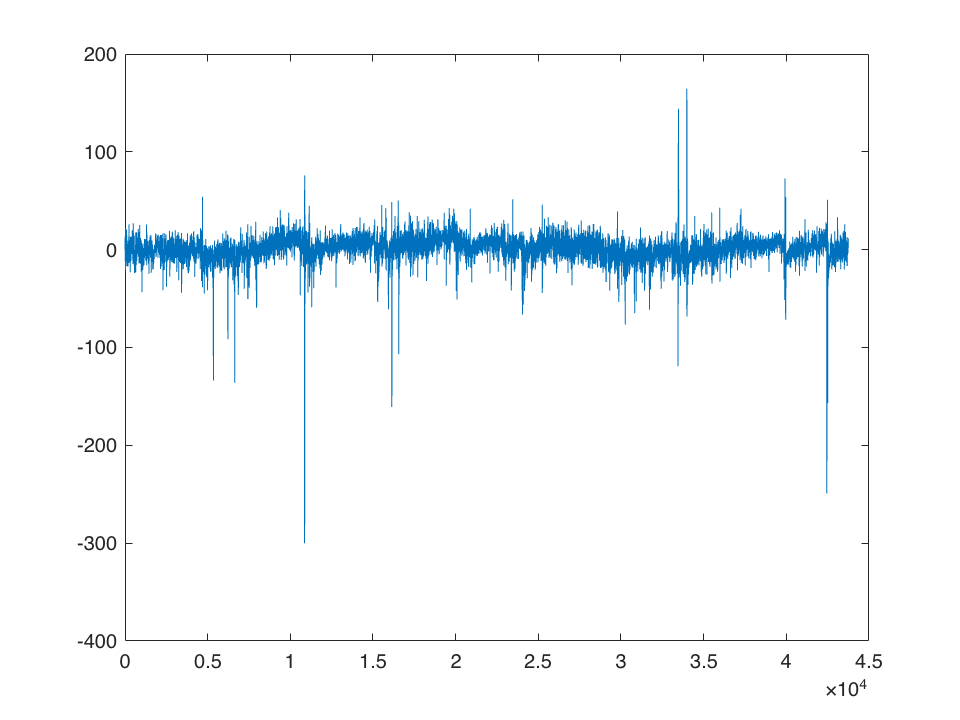

%this code is for Multiscale principal 
%component analysis of geomagnetic signal
% Hang Chen Feb 2, 2022

clear

load('CNB2000-2004.mat')

% example fro Z direction signal
Z_mag = detrend(BZ1);
x = Z_mag;

figure
plot(Z_mag)

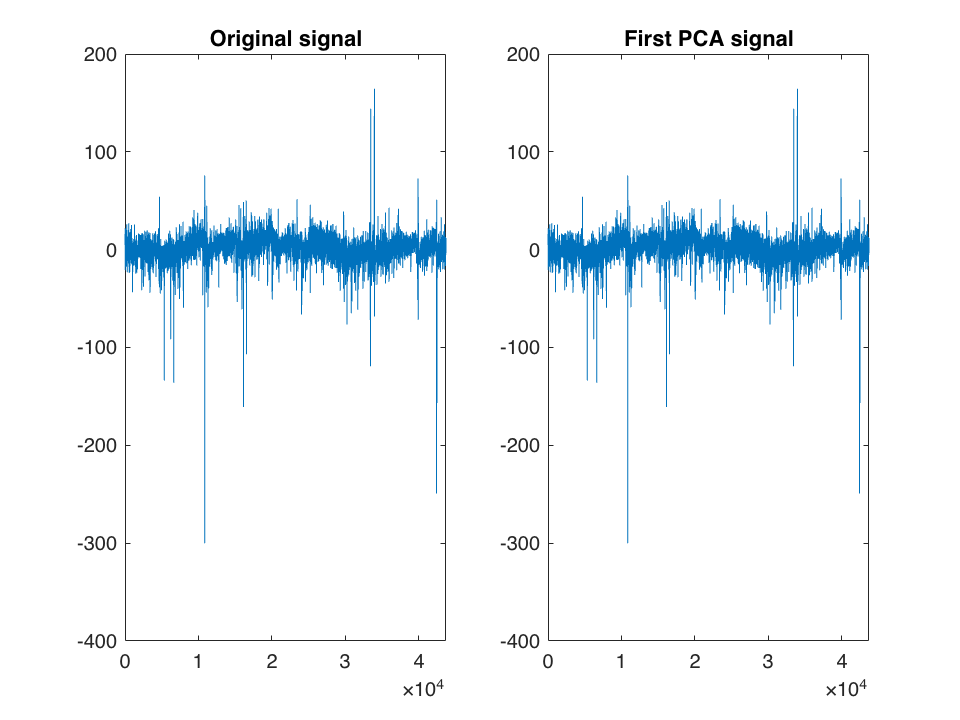

% test pca
[coeff, score, latent, tsquared, explained] = pca(x);

level = 5;
wname = 'sym4';
npc = 'heur';
[x_sim,qual,npcA] = wmspca(Z_mag,level,wname,npc);


figure 
subplot(1,2,1)
plot(x)
title('Original signal')
subplot(1,2,2)
plot(x_sim)
title('First PCA signal')

qual

qual = 100

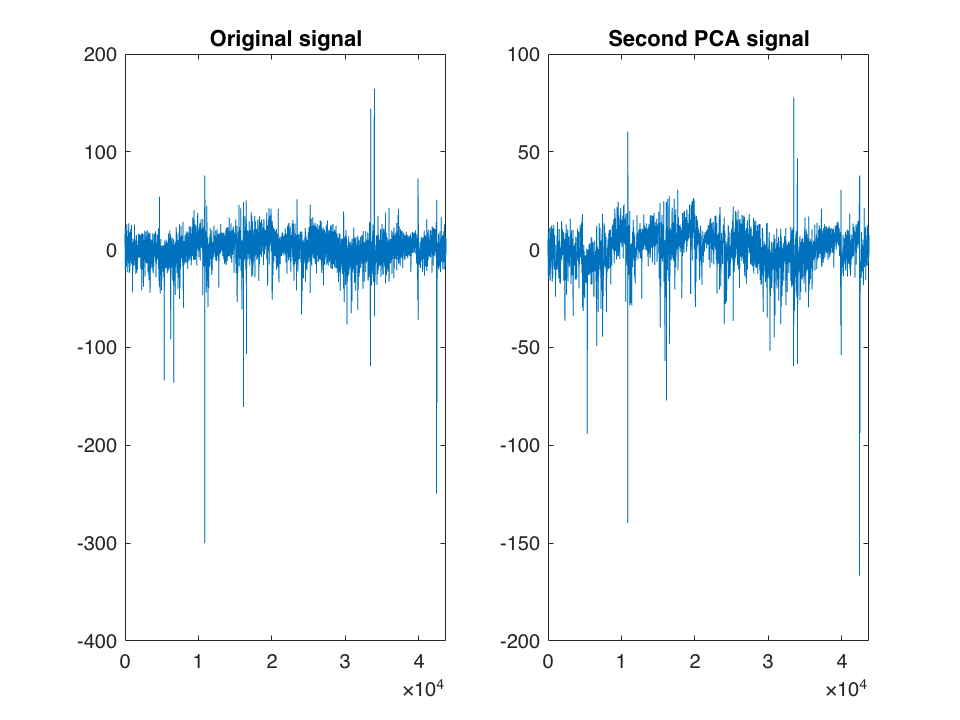


npcA(1:3) = zeros(1,1);
[x_sim,qual,npcB] = wmspca(x,level,wname,npcA);

figure 
subplot(1,2,1)
plot(x)
title('Original signal')
subplot(1,2,2)
plot(x_sim)
title('Second PCA signal')